Opg.2

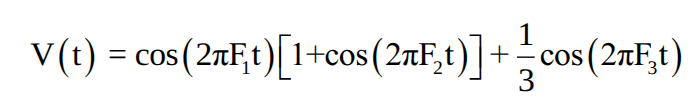

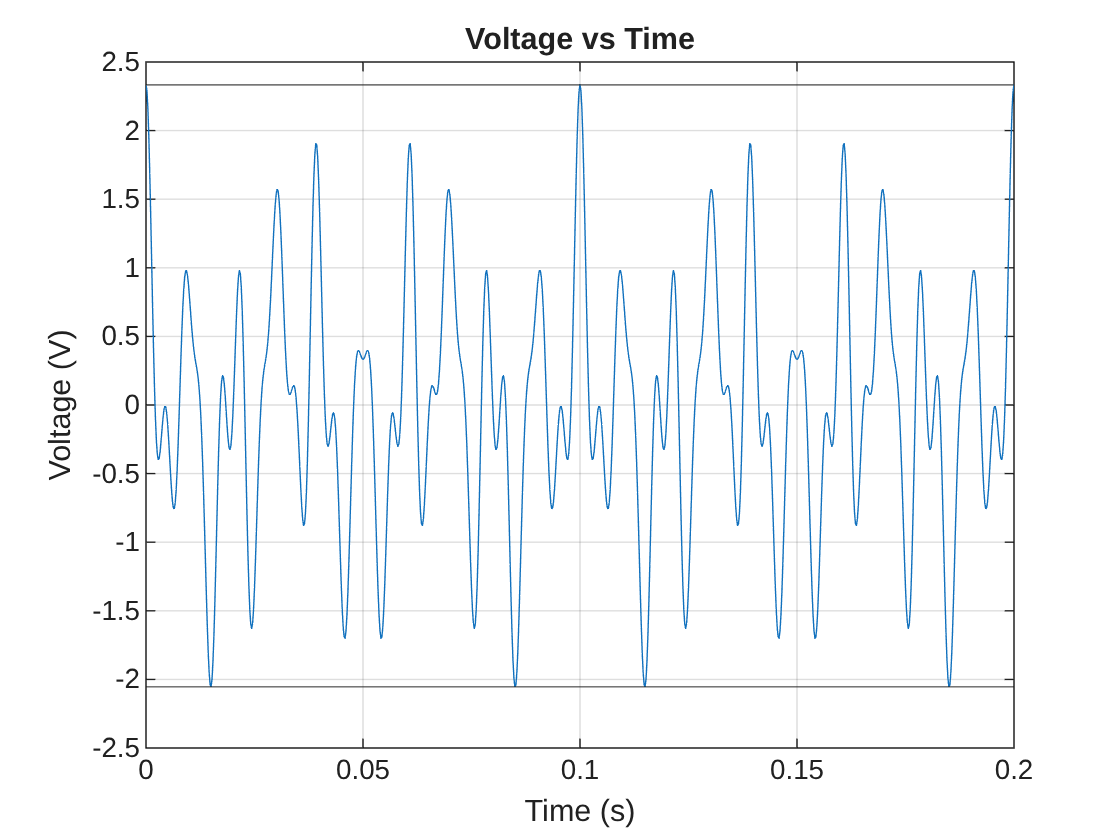

F_1 = 100; F_2 = 130; F_3 = 180; F_s = 4.6e3; N = F_s/d_F;

t = time_vec(F_s, N);

v_t = cos(2*pi*F_1*t).*(1+cos(2*pi*F_2*t))+((1/3)*cos(2*pi*F_3*t));

figure();
plot(t, v_t);
xlim([0 0.2])
yline([min(v_t) max(v_t)]);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Voltage vs Time');
grid on;

max(v_t)

ans = 2.3333

min(v_t)

ans = -2.0541

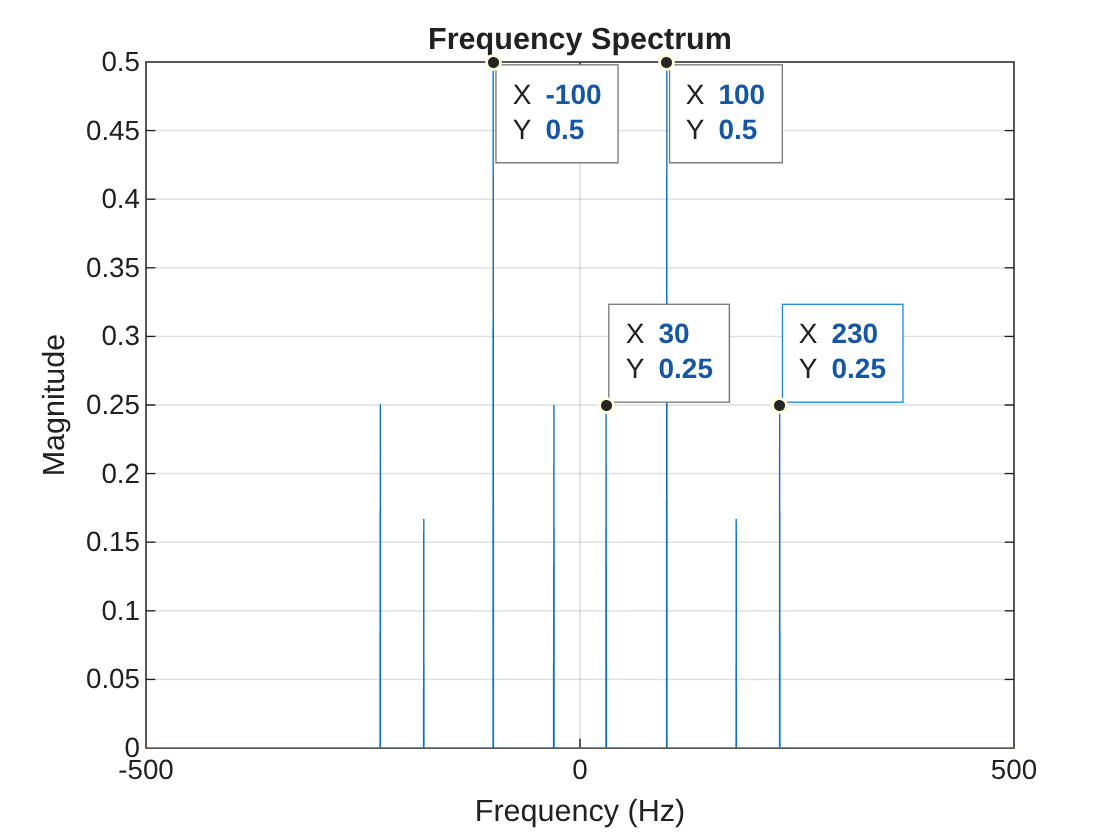

d_F = 0.1;

f = frequency_vec(F_s, N);

V_f = fftshift(fft(v_t));

figure();
plot(f, abs(V_f)/length(V_f));
xlim([-0.5e3 0.5e3])
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Spectrum');
grid on;

ax = gca;
chart = ax.Children(1);
datatip(chart,0,0.3333);
datatip(chart,30,0.25);
datatip(chart,100,0.5);
datatip(chart,230,0.25);

Ved aflæsning af grafen ses, at ved 30Hz og 230 er der 0.25 i amplitude, og ved 100Hz er der 0.5.

syms f1 f2 f3 T
simplify(cos(2*pi*f1*T)*(1+cos(2*pi*f2*T))+((1/3)*cos(2*pi*F_3*T)))

$$ans = \frac{\cos\left(360\,\pi \,T\right)}{3}+\cos\left(2\,\pi \,T\,f_{1}\right)\,\left(\cos\left(2\,\pi \,T\,f_{2}\right)+1\right)$$

Opg.4

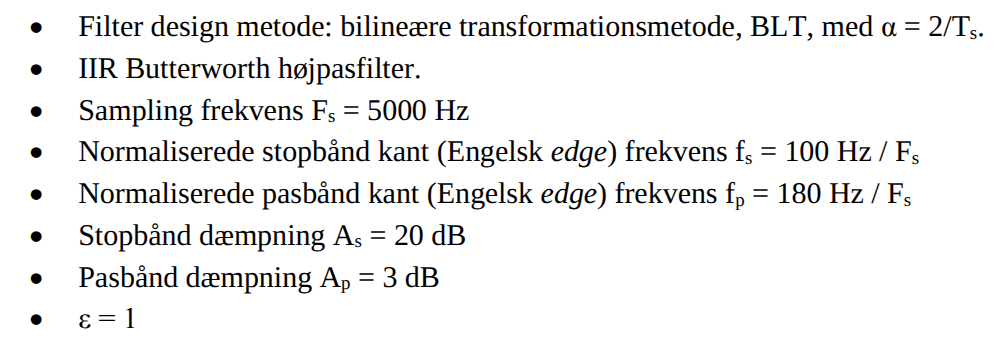

clear; clc;
F_s = 5e3; f_s = 100; f_p = 180; A_sdB = 20; A_pdB = 3;

omega_p = (2*pi*f_p)/F_s; omega_s = (2*pi*f_s)/F_s;


For at beregne analoge frekvense: $\Omega =2\cdot F_s \cdot \tan \left(\frac{\omega }{2}\right)$

Omega_p = 2*F_s*tan(omega_p/2)

Omega_p = 1.1358e+03

Omega_s = 2*F_s*tan(omega_s/2)

Omega_s = 629.1467

Beregningen for filter orden er: $n\ge \frac{\log_{10} \left(\frac{{10}^{0\ldotp 1A_{\mathrm{sdB}} } -1}{\epsilon^2 }\right)}{2\log_{10} \left(\nu_s \right)}\;,\nu_s =\frac{\Omega_p }{\Omega_s }\left(h\o \mathrm{jpas}\right)$

nu = Omega_p/Omega_s;

n = (log10((10^(0.1*A_sdB))-1))/(2*log10(nu))

n = 3.8893

Dvs. filterorden er 4. Hvor butterworth prototype filteret er:


$$H\left(s\right)=\frac{1}{s^4 +2\ldotp 6131s^3 +3\ldotp 4142s^2 +2\ldotp 6131s+1}$$


For at transformere det til et højpas skal man erstatte $s\longrightarrow \frac{\Omega_p }{s}$

b_p = 1; a_p = [1 2.6131 3.4142 2.6131 1];

[bt, at] = lp2hp(b_p, a_p, Omega_p);

tf(bt, at)


ans =
 
    s^4 + 8.063e-13 s^3 + 3.063e-10 s^2 + 7.059e-07 s
  -----------------------------------------------------
  s^4 + 2968 s^3 + 4.405e06 s^2 + 3.829e09 s + 1.664e12
 
Continuous-time transfer function.


For at transformere fra s til z domene, skal man gøre: $z=\frac{1+\frac{{\mathrm{sT}}_s }{2}}{1-\frac{{\mathrm{sT}}_s }{2}}$

[bd, ad] = bilinear(bt, at, F_s);

tf(bd, ad, 1/F_s, 'Variable', 'z^-1')


ans =
 
  0.7436 - 2.974 z^-1 + 4.461 z^-2 - 2.974 z^-3 + 0.7436 z^-4
  -----------------------------------------------------------
     1 - 3.41 z^-1 + 4.397 z^-2 - 2.538 z^-3 + 0.5529 z^-4
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


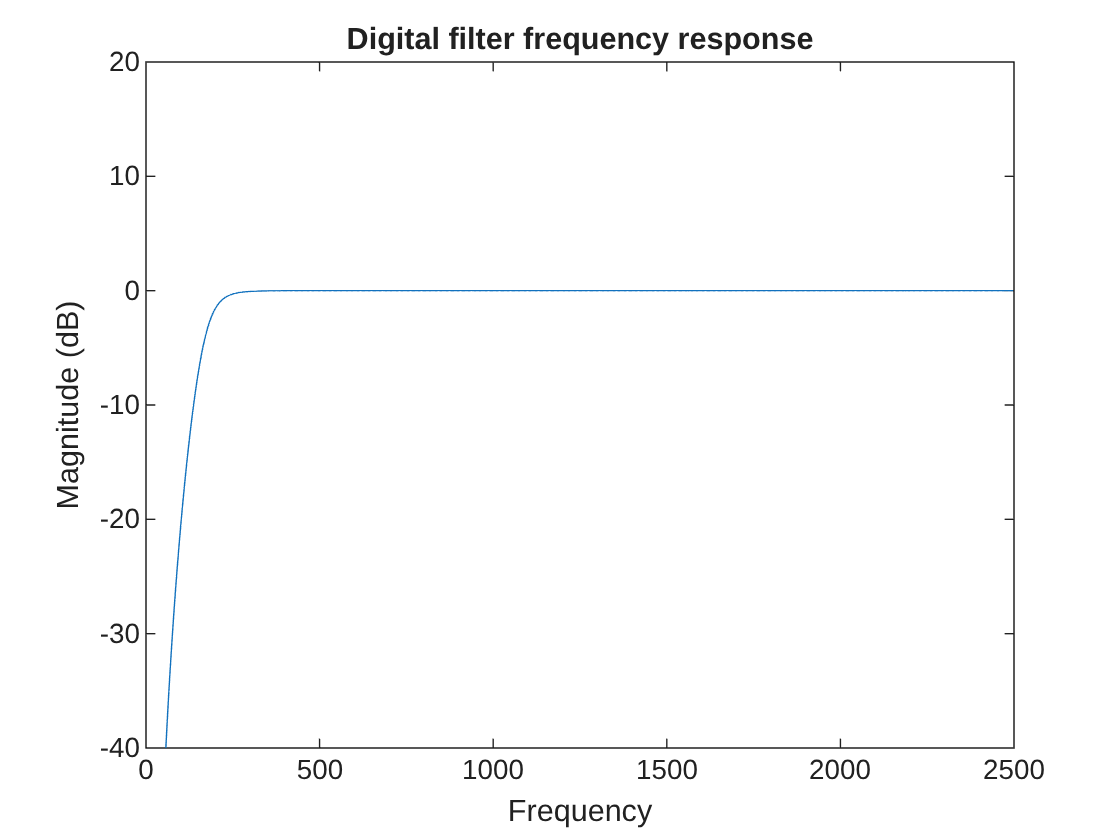

[h, f] = freqz(bd, ad, 1024, F_s);

figure();
plot(f, 20*log10(abs(h)));
ylim([-40 20]);
xlabel('Frequency');
ylabel('Magnitude (dB)');
title('Digital filter frequency response');

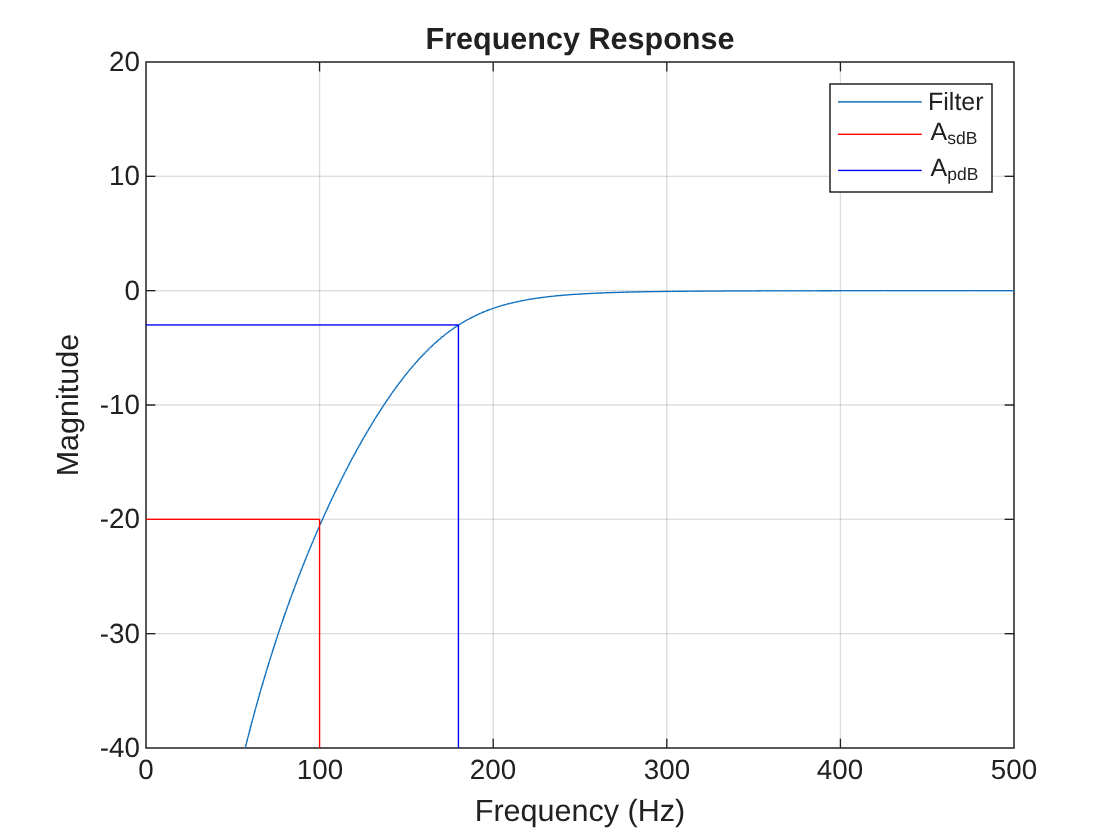

    figure();
    plot(f, 20*log10(abs(h)))
    ylim([-40 20]);
    xlim([0 500]);
    line([f_s f_s],[-A_sdB -40], 'Color','r');
    line([f_p f_p], [-A_pdB -40], 'Color', 'b');
    line([0 f_s], [-A_sdB -A_sdB], 'Color', 'r');
    line([0 f_p], [-A_pdB -A_pdB], 'Color', 'b');
    legend('Filter', 'A_{sdB}', 'A_{pdB}');

    %labels
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('Frequency Response');
    grid on;